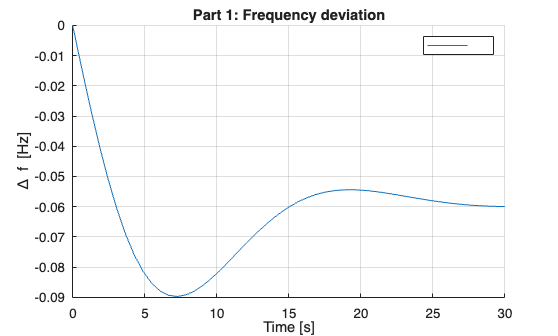

%% Q1
mdl = 'part1cde';
load_system(mdl);
set_param(mdl, 'StopTime', '30');

%% Run simulation
out = sim(mdl);

%% q1c

fromSim = out.get('omegaPlot');

figure;
hold on; grid on;
for i = 1:fromSim.numElements
    toPlot = fromSim.get(i);
    plot(toPlot.Values.Time, toPlot.Values.Data, 'DisplayName', toPlot.Name);
end
xlabel('Time [s]'); ylabel('\Delta f [Hz]');
title('Part 1: Frequency deviation'); saveas(gcf, 'part1_freq.png');
legend('show');